# 创建一个石墨烯TB模型并拟合参数

## 创建石墨烯TB模型(step by step)

- 声明一个空的模型；初始化其轨道数

Graphene = HR(2);

- 修改POSCAR格式

*generated by phonopy*

*   1.0*

*     2.4604399204208875    0.0000000000000000    0.0000000000000000*

*    -1.2302199602104438    2.1308034755698513    0.0000000000000000*

*     0.0000000000000000    0.0000000000000000   10.0000000000000000*

*C*

*   2*

*Direct*

*  0.6666666666666666  0.3333333333333333  0.0000000000000000 *`C p z `

*  0.3333333333333334  0.6666666666666667  0.0000000000000000 *`C p z`

- 导入POSCAR

Graphene = Graphene <'POSCAR_pz';
% Graphene = Graphene.input_orb_struct('POSCAR')
Graphene.orbL

ans =    0.666666666666667   0.333333333333333                   0
   0.333333333333333   0.666666666666667                   0


- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 0];
Accuracy = 3;
r_max_search = 5;
Graphene = Graphene.nn(search_range,Accuracy ,r_max_search);

Generating 2/2 th orb nn information ...
Giving nn_level for 32/32 th hopping  ...


- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = Graphene.nn_information();

- 这里我们取最近邻hopping

Graphene = Graphene.H_TBSK_gen('level_cut',1)

Generating Symbolic Hopping term ...< ok >
Setting NRPT 5/5 ...


Graphene =   HR with properties:

    WAN_NUM: 2
      NRPTS: 5
       Type: 'mat'
      HcoeL: [2×2×5 sym]
      HnumL: [2×2 double]
    vectorL: [5×3 double]


- 查看一下体系的未知量（symbolic）

Graphene.symvar_list

$$ans = {\mathrm{VppP}}_{1}$$

## 利用MATLAB(2020)控件调整参数

- 导入 KPOINTS信息 高对称点 高对称路径

 Graphene = Graphene<'KPOINTS';

- 创建滑块


VppP_1 = 2.3;
Fermi = 0;

- 给TB中的符号化变量赋值

Graphene_n = Graphene.Subsall();

- 生成 hr.dat

Graphene_n.Gen_hr()

Writing hr.dat - NRPT:5/5 ...


ans =      3


- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

BAND calculating 60/60 ...


- 画出能带

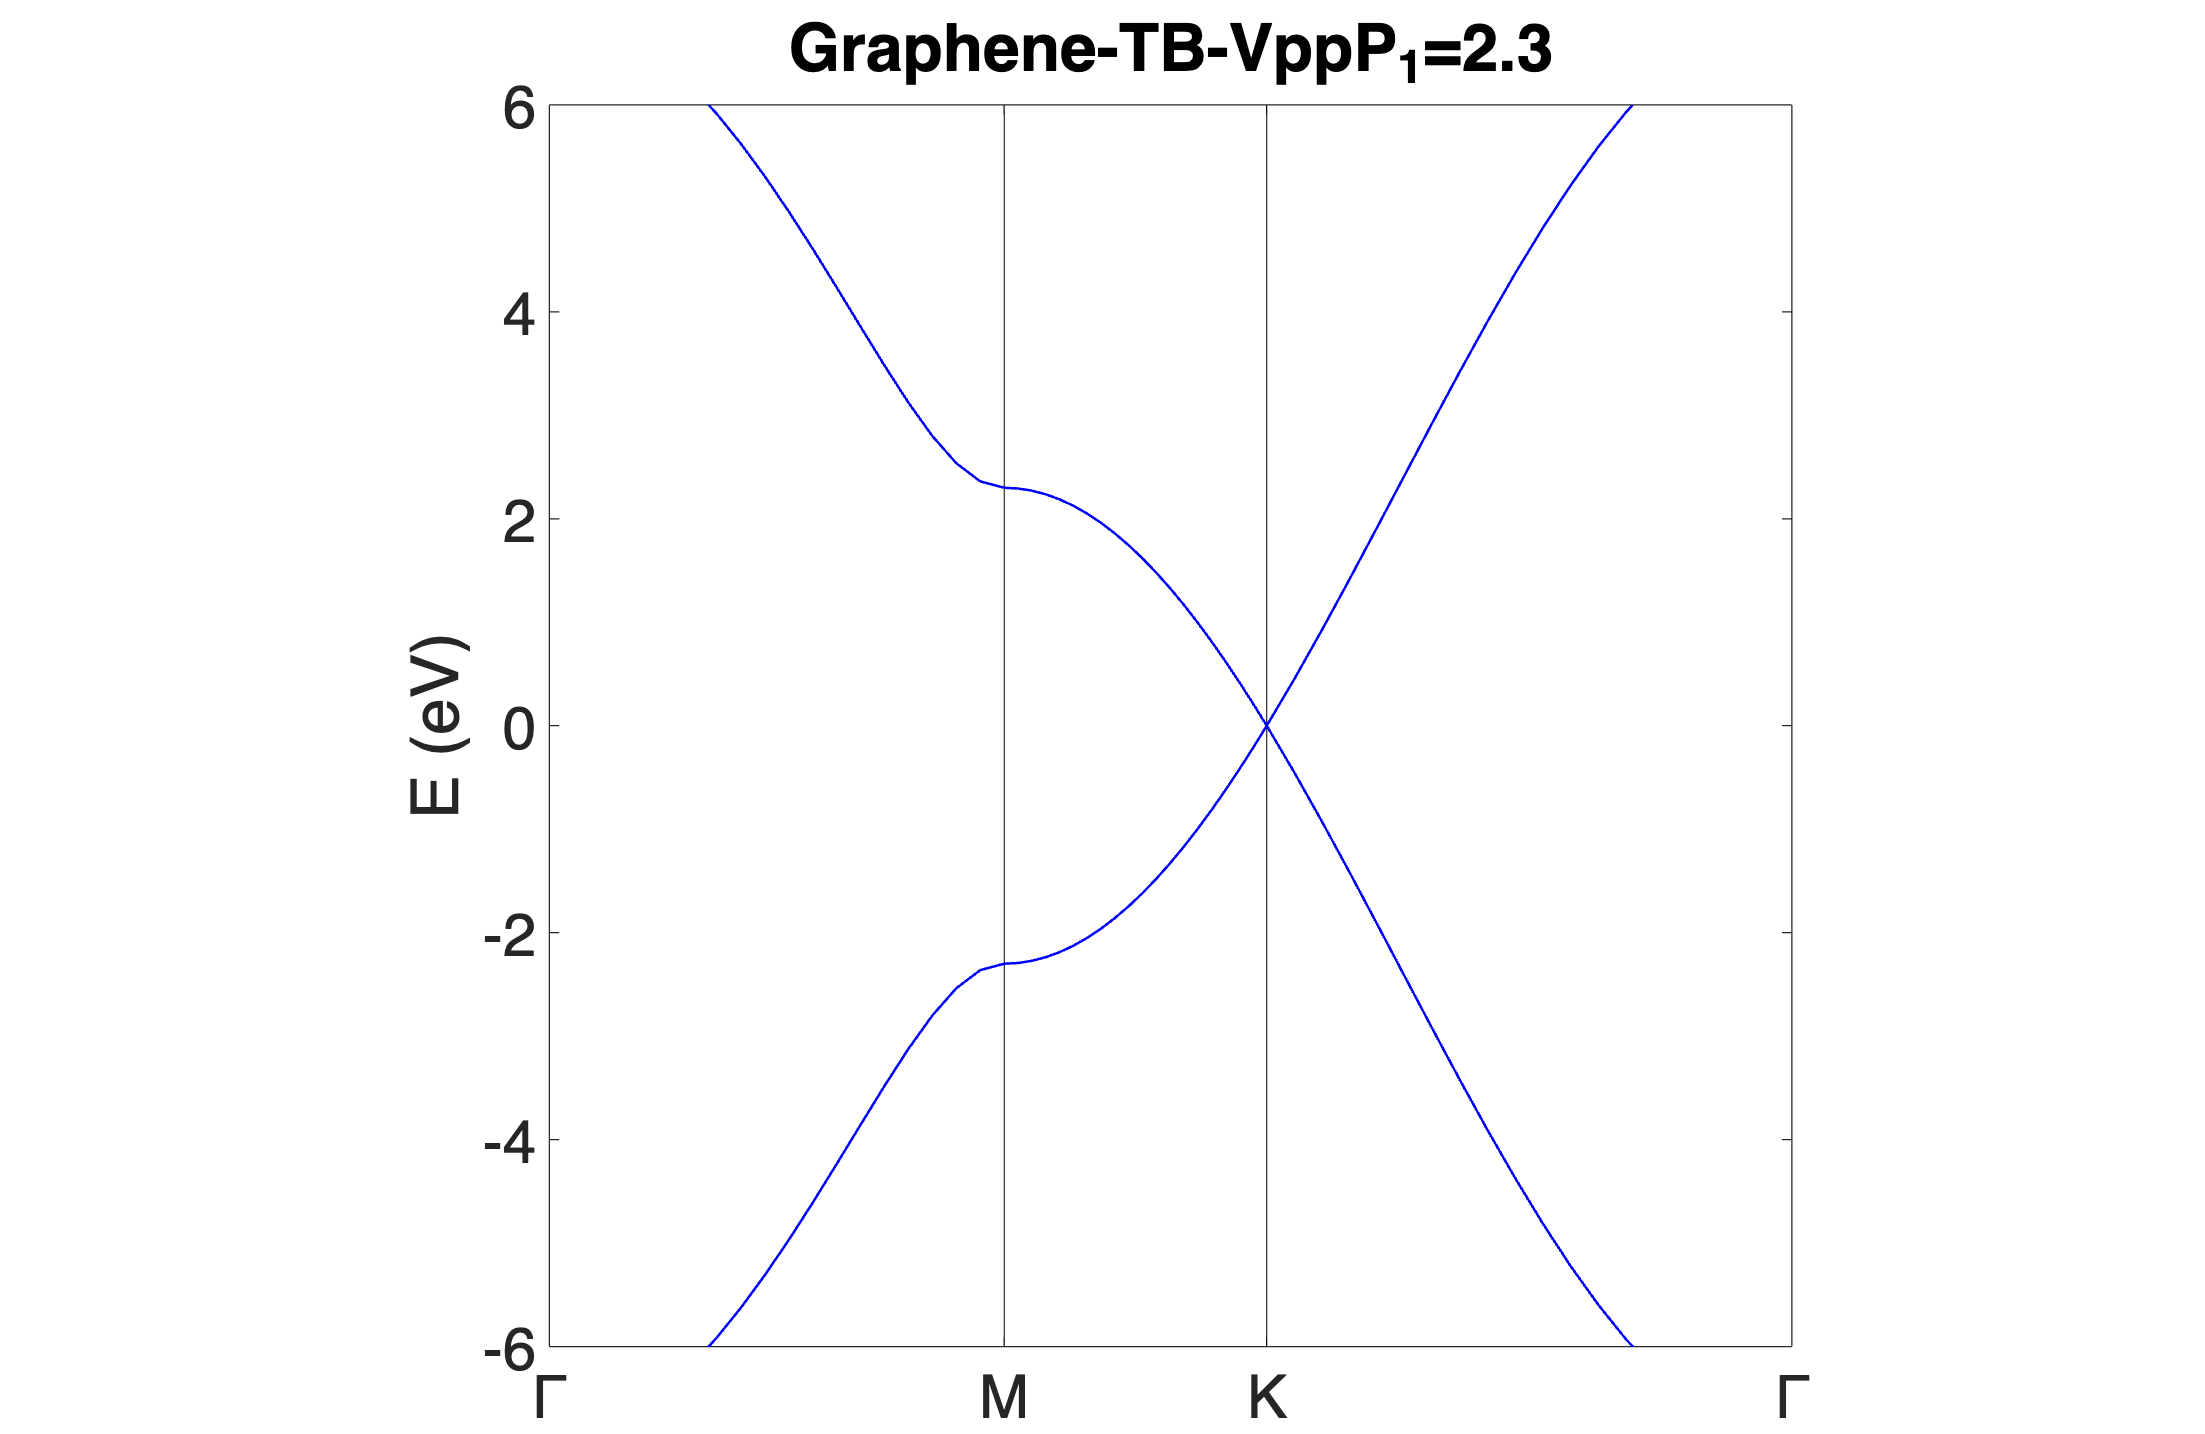

bandplot(EIGENCAR,[-6,6],...
    'title',"Graphene-TB-VppP_1="+string(VppP_1),'Color','b');

## TBSK单参数拟合

设定拟合范围：

EIGENCAR_DFT = EIGENVAL_read;
options_extra.NBAND_range_DFT = [4:5];
options_extra.NBAND_range = [1:2];
options_extra.klist_range = [30:50];
%options_extra.E_range = [-2:2];

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

Graphene_single = Graphene;
Loss_func_GrapheneTB = @(para) vasplib.loss_func(para, ...
    'FITobj','Graphene_single',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)                     

Loss_func_GrapheneTB = function_handle with value:
    @(para)vasplib.loss_func(para,'FITobj','Graphene_single','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


 
 Func-count     x          f(x)         Procedure
    1        1.76393      1.68421        initial
    2        2.23607      1.06079        golden
    3        2.52786     0.786353        golden
    4         2.7082     0.677762        golden
    5        2.81966     0.689685        golden
    6        2.74192     0.668984        parabolic
    7        2.75261     0.668856        parabolic
    8        2.74834     0.668771        parabolic
    9        2.74848     0.668773        parabolic
   10        2.74589     0.668795        golden
   11        2.74767     0.668763        parabolic
   12        2.74699     0.668754        golden
   13        2.74657     0.668763        golden
   14        2.74711     0.668756        parabolic
   15        2.74694     0.668754        parabolic
   16         2.7468     0.668752        golden
   17        2.74671     0.668756        golden
   18        2.74685     0.668752        golden
   19        2.74676     0.668753        golden
 
Optimization

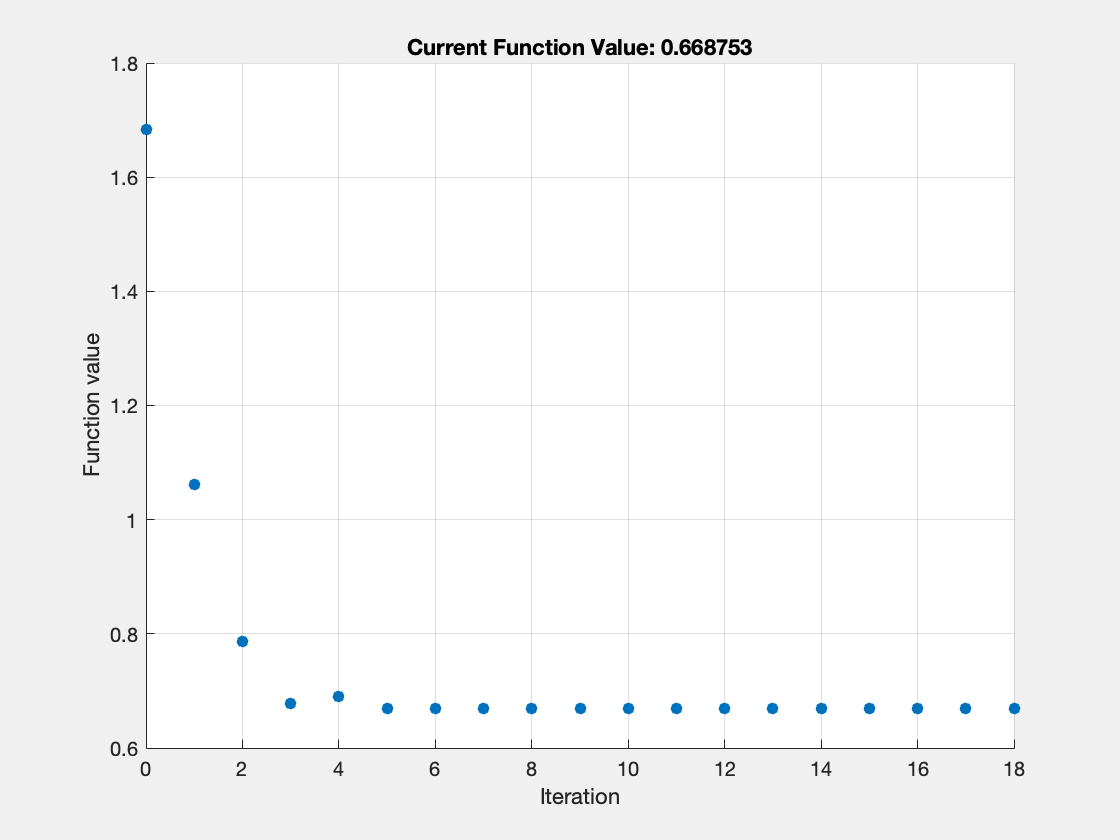

options = optimset('PlotFcns',@optimplotfval,'Display','iter');
VppP_1 = fminbnd(Loss_func_GrapheneTB,1,3,options);

Graphene_single_n = Graphene_single.subs(Graphene_single.symvar_list(1),VppP_1);
EIGENCAR = Graphene_single_n.EIGENCAR_gen();

BAND calculating 60/60 ...


- 使用bandcompare画出能带

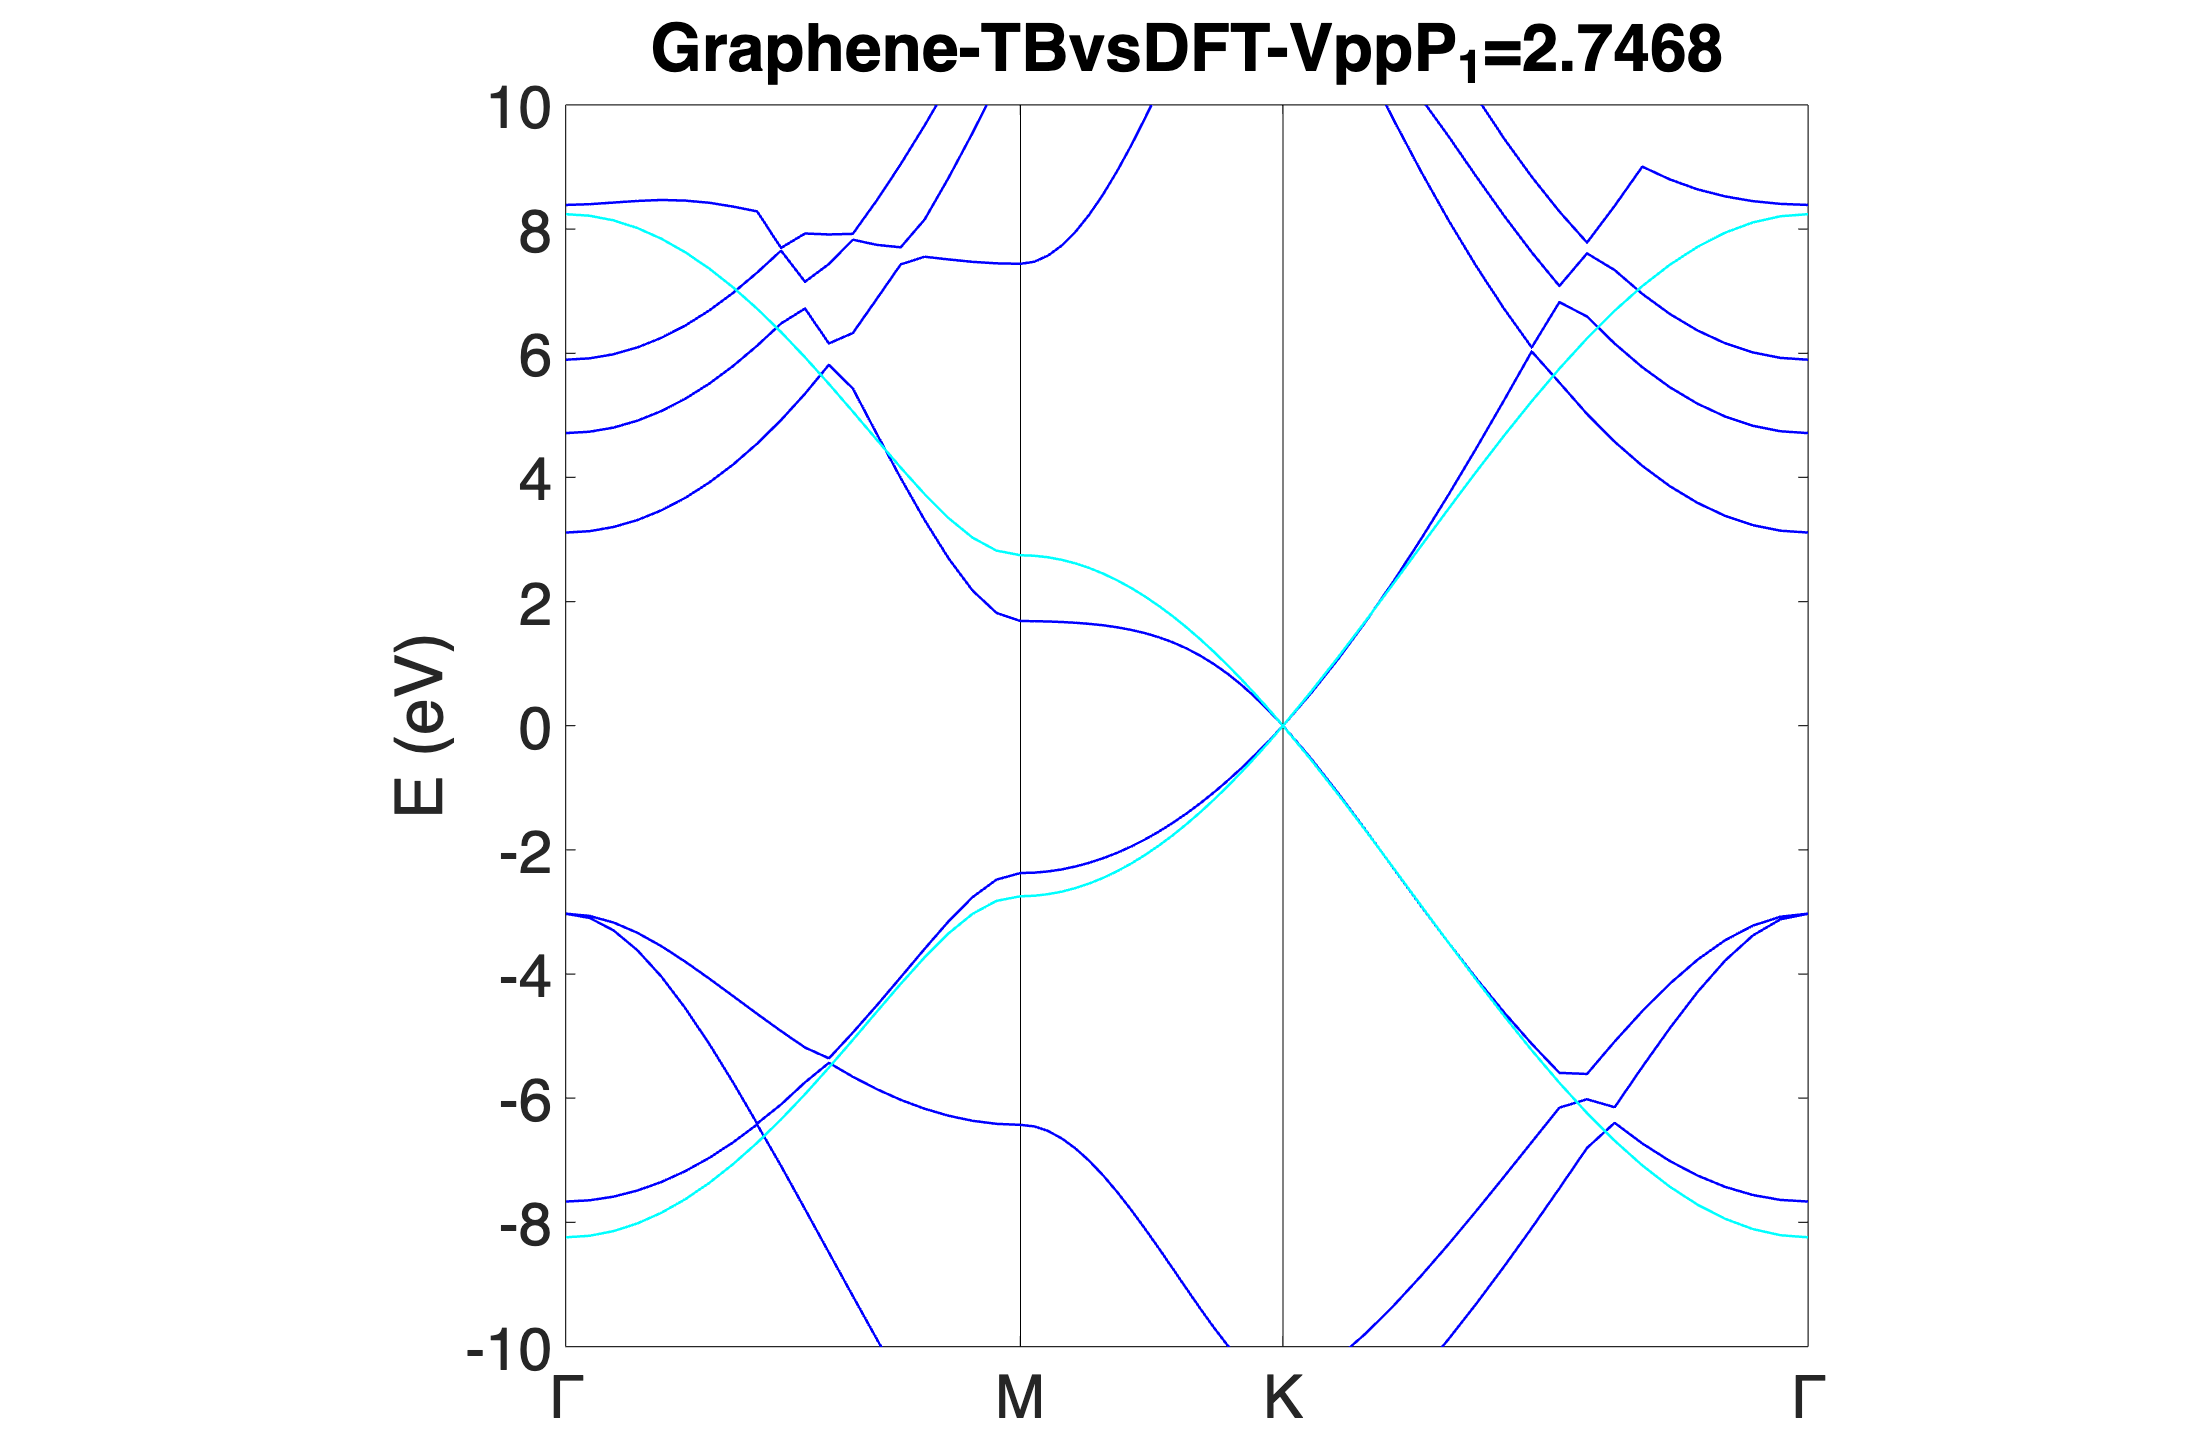

bandplot({EIGENCAR_DFT,EIGENCAR} ,[-10,10],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## 利用MATLAB(2020)控件调整参数 - DFT

- 导入DFT数据

EIGENCAR_DFT = EIGENVAL_read; 

- 引入此近邻

Graphene = Graphene.H_TBSK_gen('level_cut',2); 

Generating Symbolic Hopping term ...< ok >
Setting NRPT 7/7 ...


Graphene.symvar_list

$$ans = \left(\begin{array}{cc} {\mathrm{VppP}}_{1} & {\mathrm{VppP}}_{2} \end{array}\right)$$

- 创建滑块

VppP_1 = 2.4;
VppP_2 = 0.4;
Fermi = 2.4;

- 给TB中的符号化变量赋值

Graphene = Graphene<'KPOINTS';
Graphene_n = Graphene.Subsall();

- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

BAND calculating 60/60 ...


- 使用bandcompare画出能带

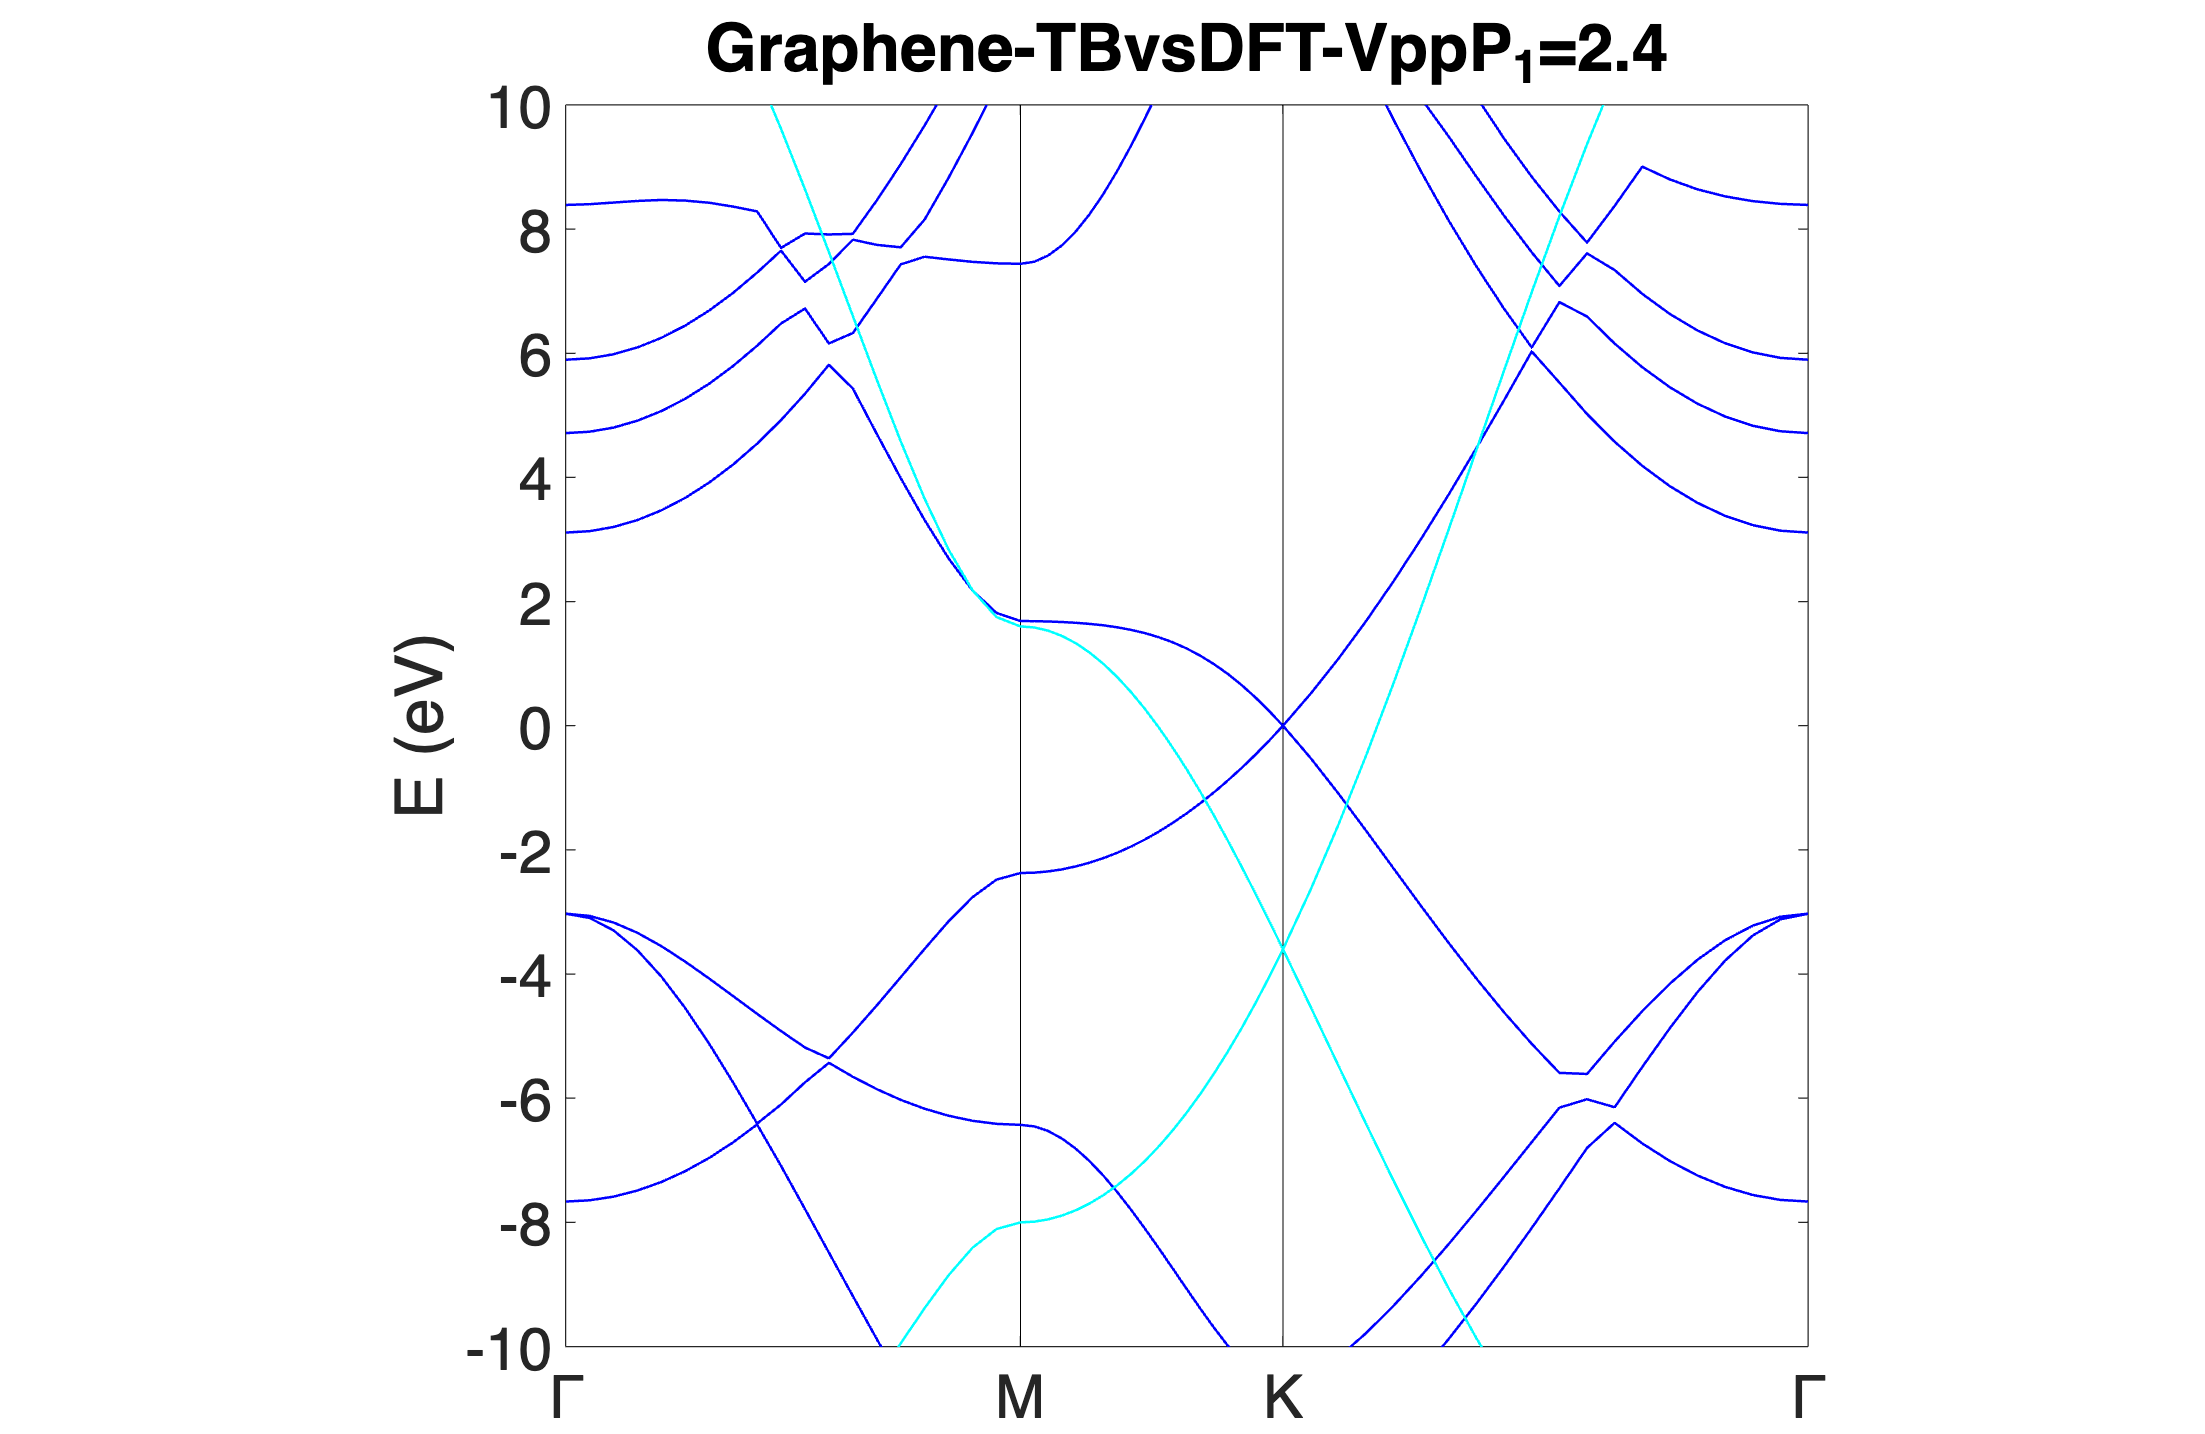

bandplot({EIGENCAR_DFT,EIGENCAR} ,[-10,10],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## 利用NM办法多参数拟合DFT

clear;
EIGENCAR_DFT = EIGENVAL_read; 

generated by phonopy

   1.0

     2.4604399204208875    0.0000000000000000    0.0000000000000000

    -1.2302199602104438    2.1308034755698513    0.0000000000000000

     0.0000000000000000    0.0000000000000000   10.0000000000000000

C

   8

Direct

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C s I

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p x

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p y

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C s I

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p x

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p y

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p z 

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p z

### 创建模型 Script模式

Graphene = HR.from_POSCAR_SE('POSCAR',...
'Type','list',...
'search_range' ,[2 2 0],...
'r_max',2,...8
'level_cut',2);

Generating 8/8 th orb nn information ...
Giving nn_level for 96/96 th hopping  ...
Generating Symbolic Hopping term ...< ok >
Setting NRPT 5/5 ...


$$\left(\begin{array}{cccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

### 利用MATLAB(2020)控件调整参数 - DFT

E__6_0 = -7;
E__6_1 = 0;
VppP_1 = 2.7;
VppS_1 = -4;
VspS_1 = -4;
VssS_1 = 4;
Fermi  = 0;

Graphene_n = Graphene.Subsall();

- 生成能带

- 画出能带

BAND calculating 60/60 ...


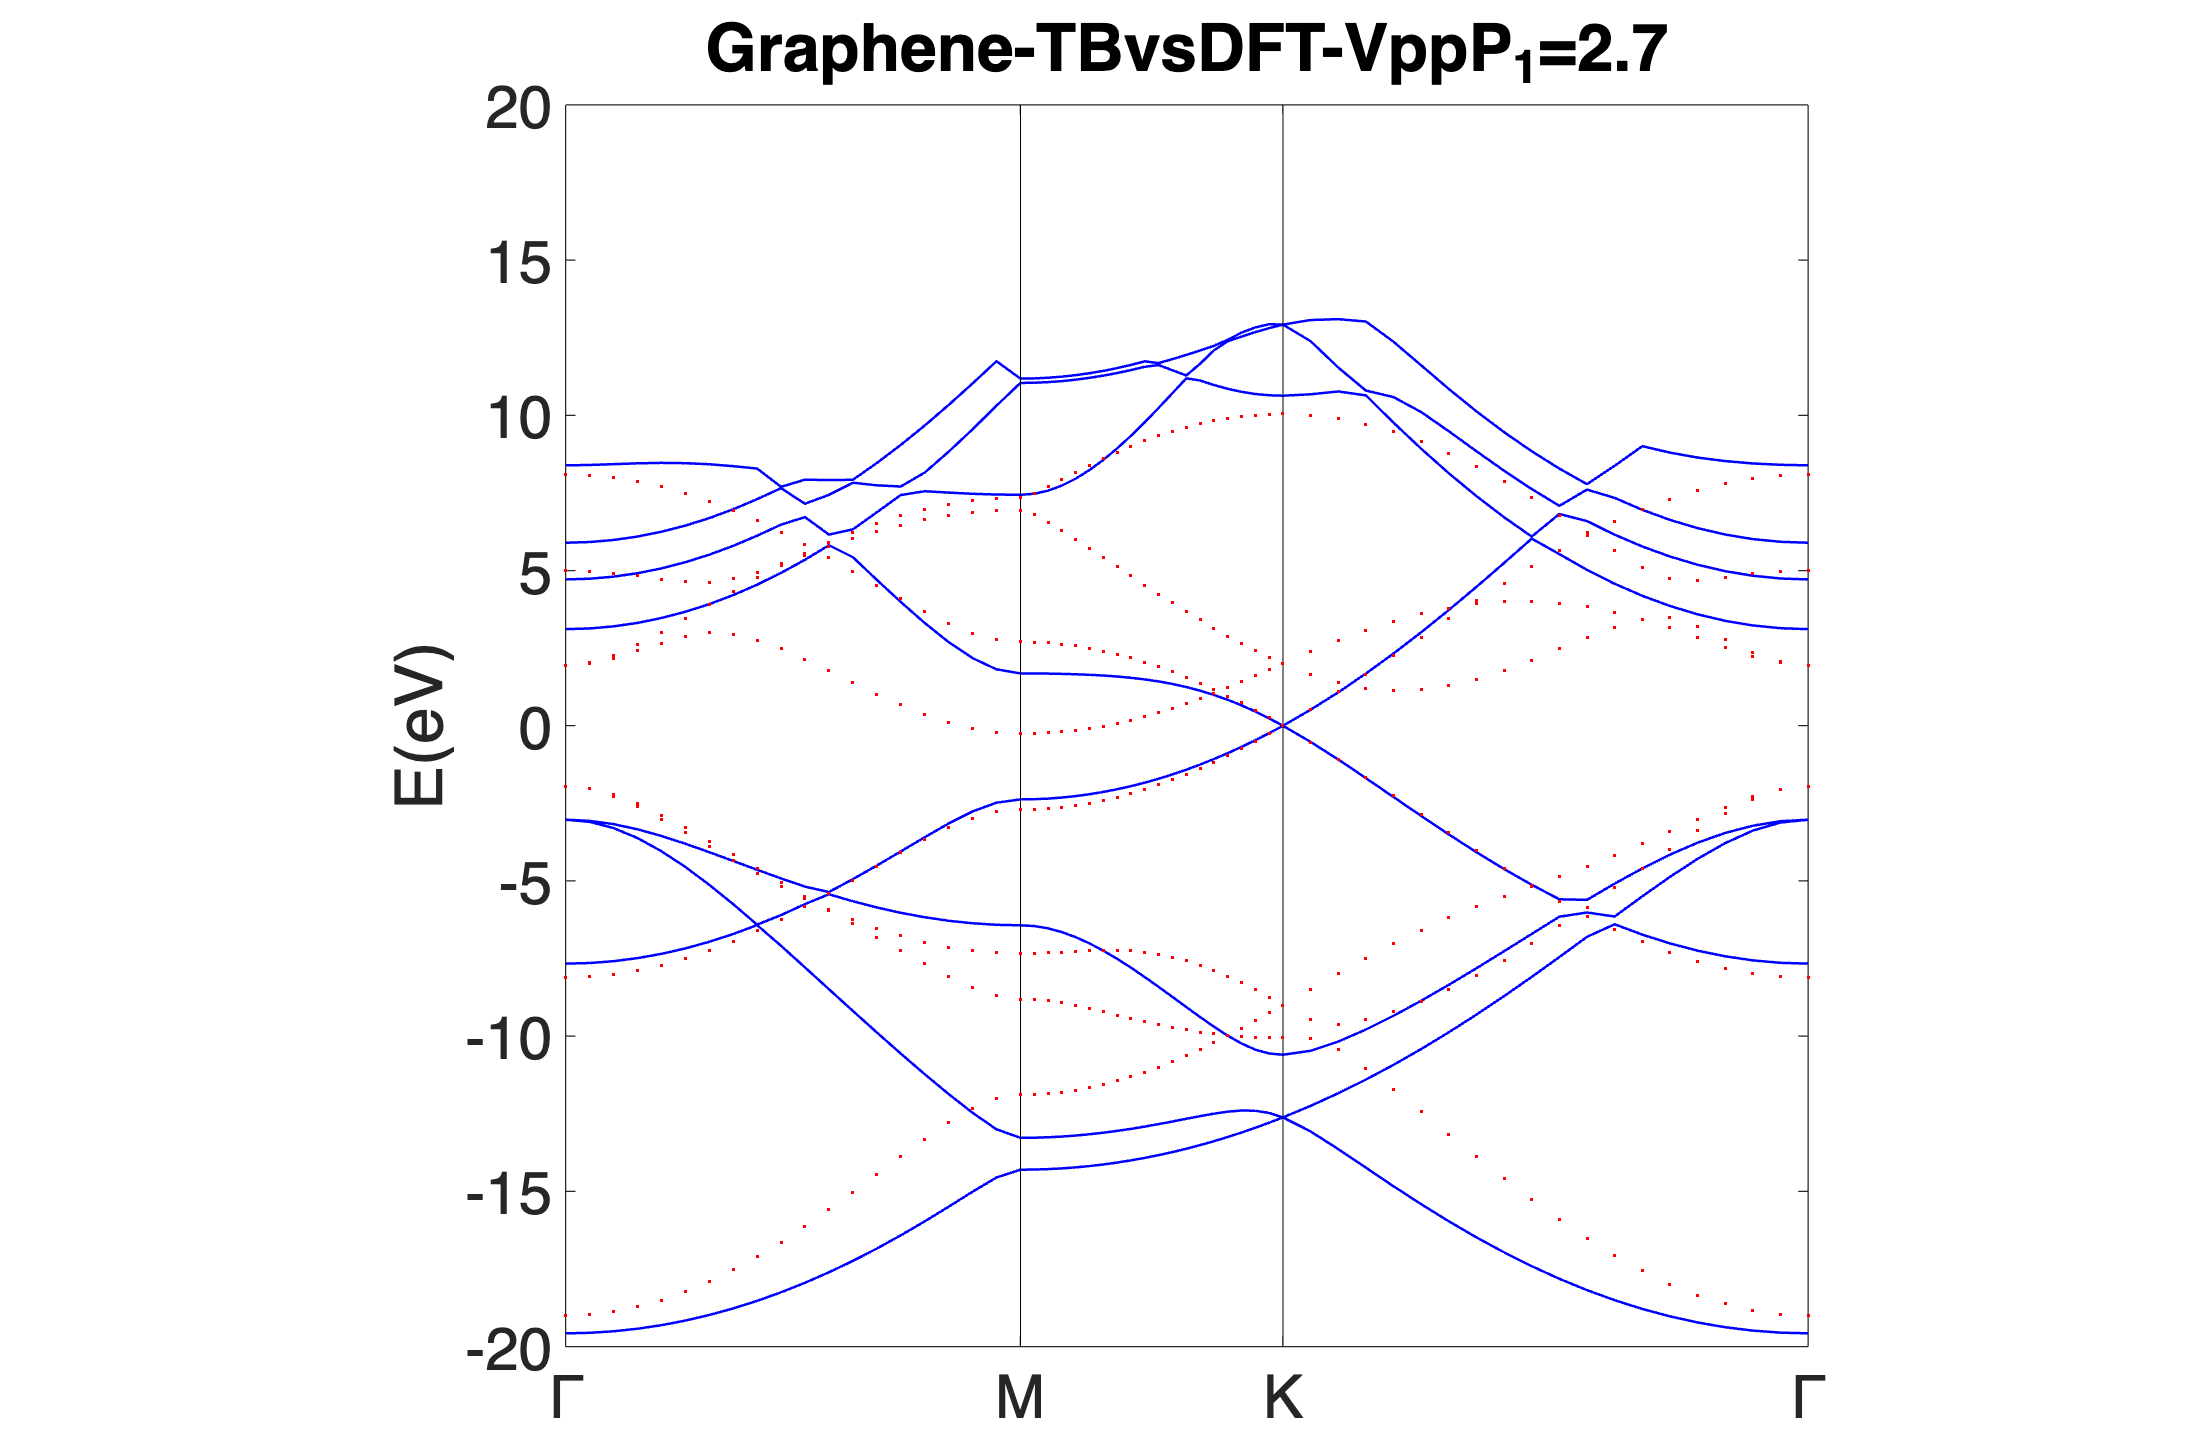

vasplib.bandcompare(Graphene_n.EIGENCAR_gen()-Fermi,EIGENCAR_DFT, [-20,20],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

### NM

#### 拟合参数设置

设定拟合范围：

options_extra.NBAND_range_DFT = [1:4];
options_extra.NBAND_range = [1:4];
options_extra.klist_range = ':';

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

Graphene_single = subs(Graphene,Graphene.symvar_list(2),0);
Loss_func_TB = @(para) vasplib.loss_func(para, ...
    'FITobj','Graphene',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)          

Loss_func_TB = function_handle with value:
    @(para)vasplib.loss_func(para,'FITobj','Graphene','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


#### 初值给定

Graphene = Graphene.subs([sym('E__6_1') sym('VppP_1')],[0,2.71353]);
Graphene.symvar_list

$$ans = \left(\begin{array}{cccc} E_{0}^{6} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

x0 = [-7,-4,-4,4];

#### 进行拟合

 
 Iteration   Func-count         f(x)         Procedure
     0            1           2.6974         
     1            5          2.55176         initial simplex
     2            7          2.44126         expand
     3            8          2.44126         reflect
     4            9          2.44126         reflect
     5           11          2.22082         expand
     6           12          2.22082         reflect
     7           13          2.22082         reflect
     8           15          1.95555         expand
     9           16          1.95555         reflect
    10           18          1.67641         expand
    11           20          1.35815         expand
    12           21          1.35815         reflect
    13           23          1.31794         reflect
    14           24          1.31794         reflect
    15           26          1.31794         contract inside
    16           28          1.31794         contract inside
    17           30          1

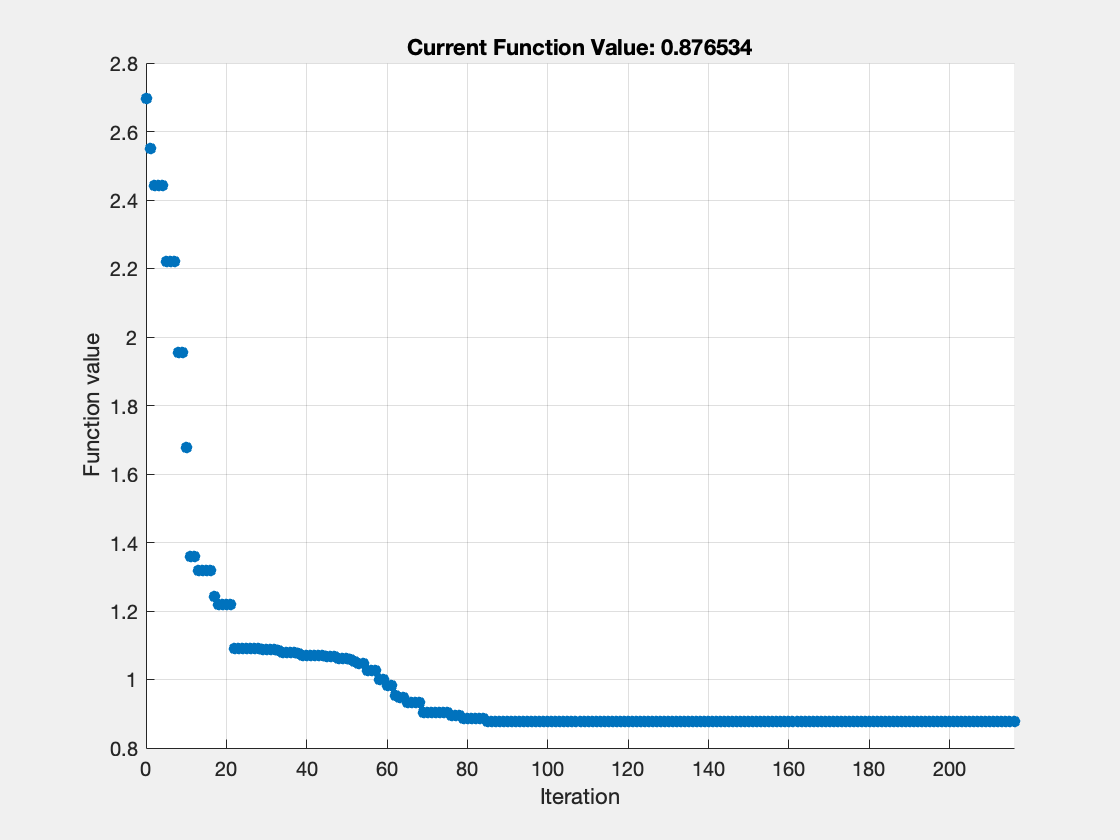

options = optimset('PlotFcns',@optimplotfval,'Display','iter');
x = fminsearch(Loss_func_TB,x0,options);

#### 拟合结果

[Graphene_n,EQL] = Graphene.subs(x);
EQL

$$EQL = \left(\begin{array}{cccc} E_{0}^{6}=-4.27945 & {\mathrm{VppS}}_{1}=-4.16767 & {\mathrm{VspS}}_{1}=-9.94658 & {\mathrm{VssS}}_{1}=5.09071 \end{array}\right)$$

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

BAND calculating 60/60 ...


- 画出能带

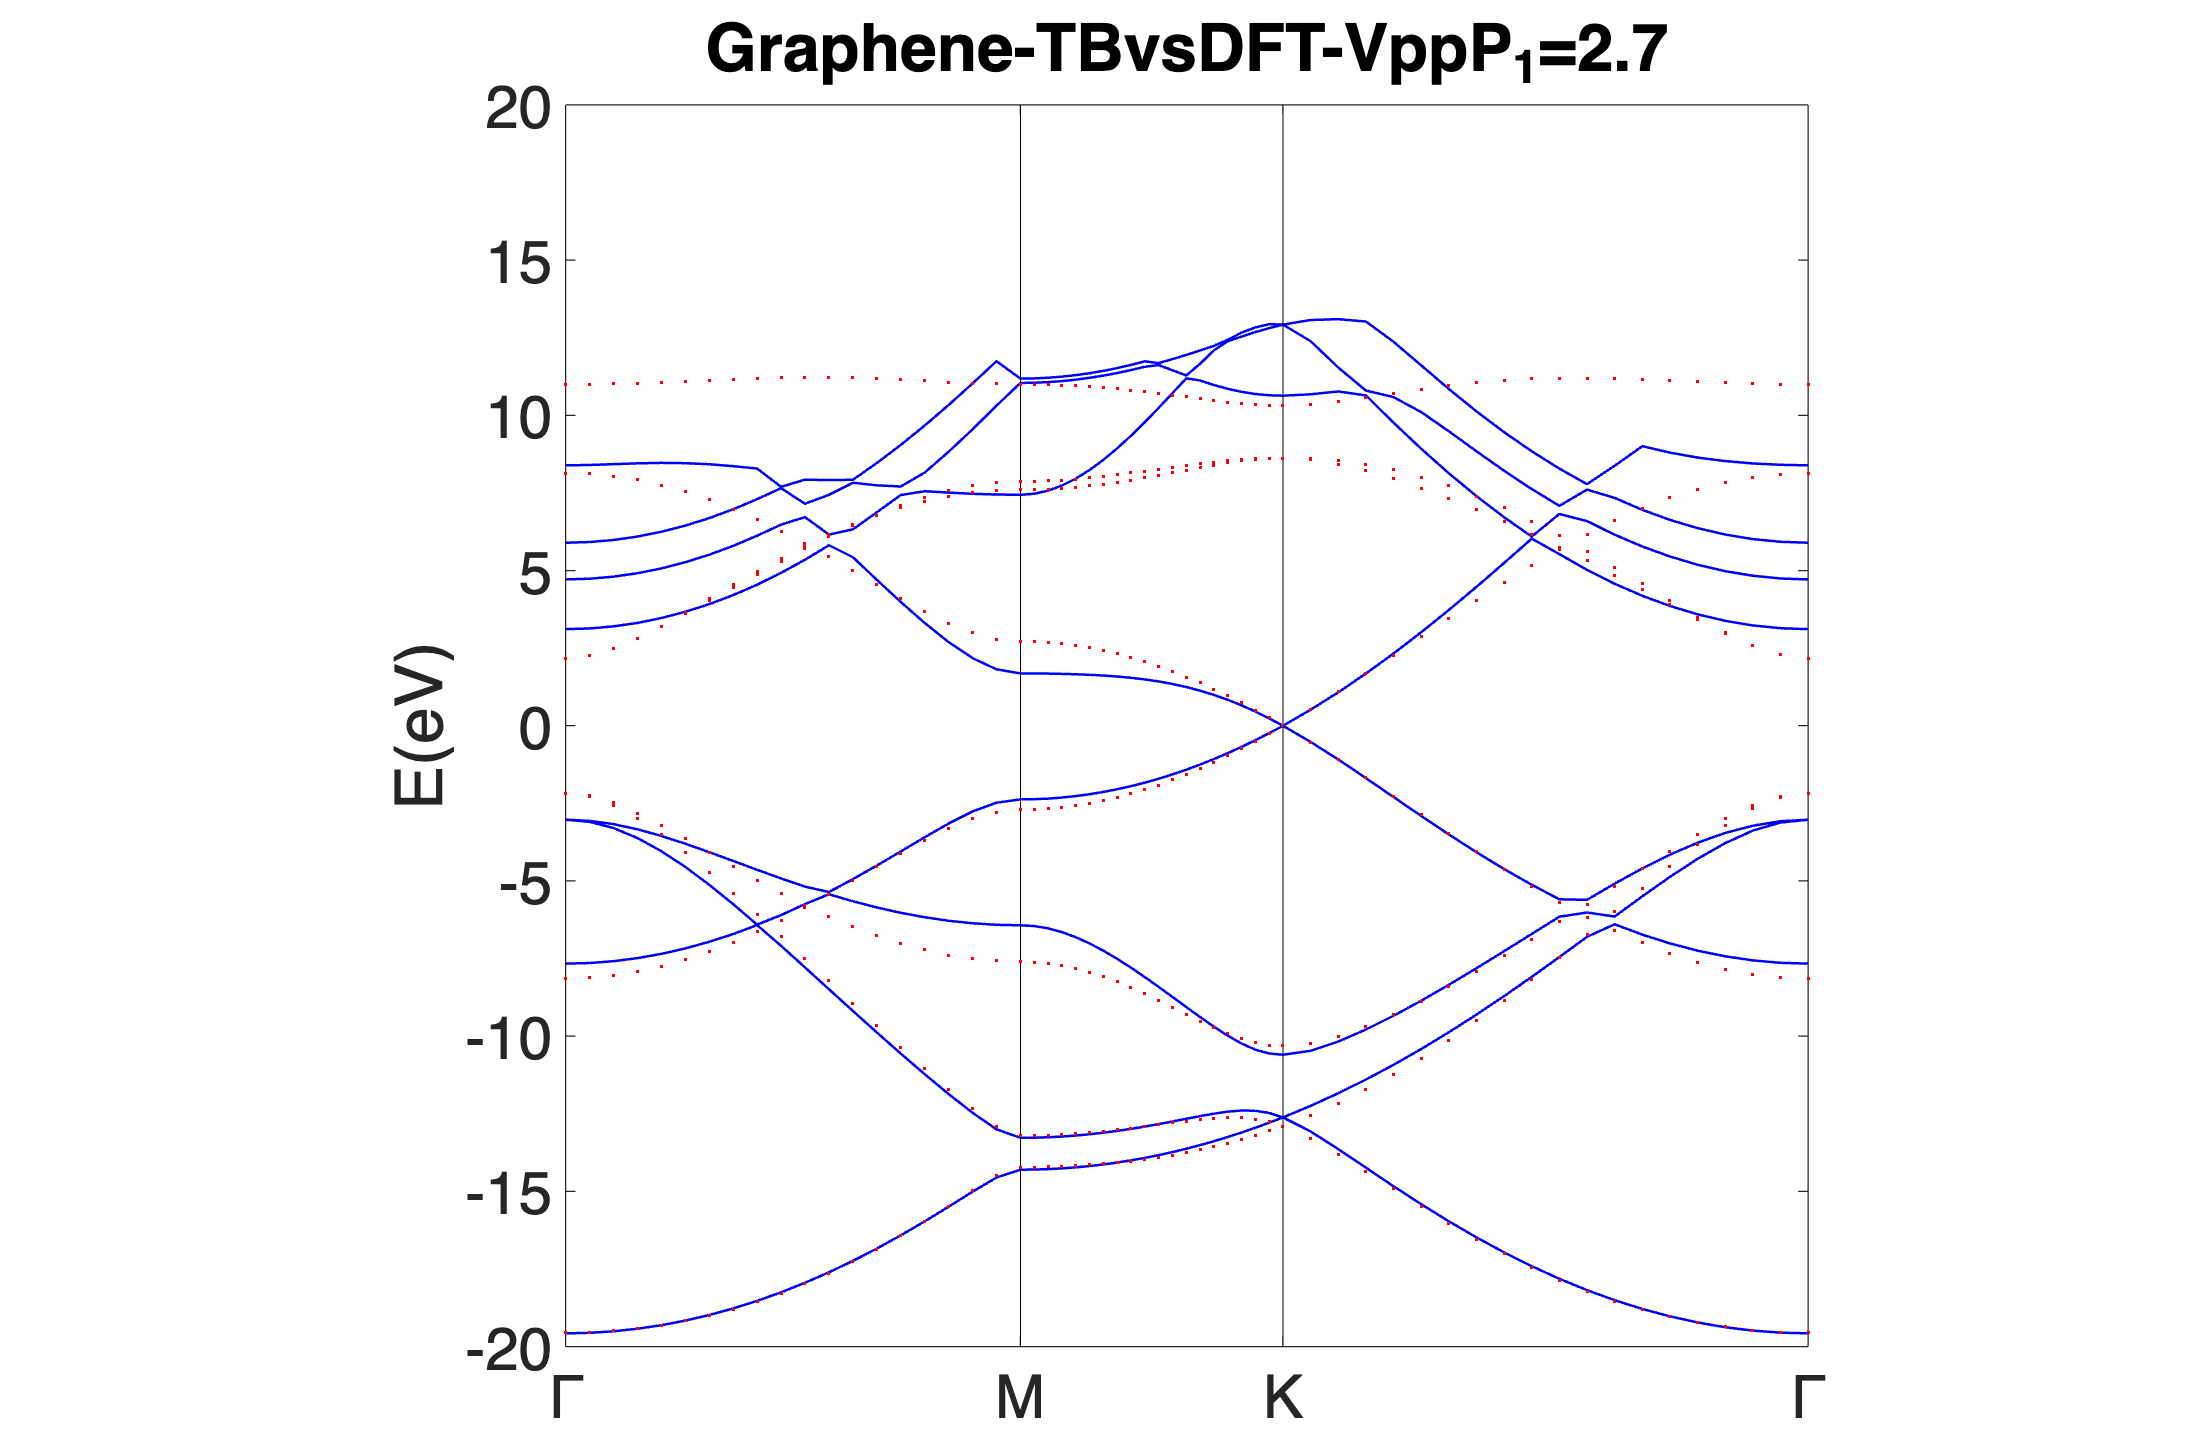

vasplib.bandcompare(EIGENCAR,EIGENCAR_DFT ,[-20,20],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## Bayes 拟合（还不完善 慎用）

我们尝试在什么都不知道的情况下拟合能带

开启**delta rule**

Graphene = HR.from_POSCAR_SE('POSCAR',...
'Type','mat',...
'search_range' ,[2 2 0],...
'r_max',4,...
'level_cut',2,...
'deltarule',1);

Generating 8/8 th orb nn information ...
Giving nn_level for 576/576 th hopping  ...
Generating Symbolic Hopping term ...< ok >
Setting NRPT 7/7 ...
applying delta rule ...


$$\left(\begin{array}{ccccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} & \delta \end{array}\right)$$

偶然情况下 我们可以参考 DFT2wannier的结果 (轨道顺序一致) （就没成功过）

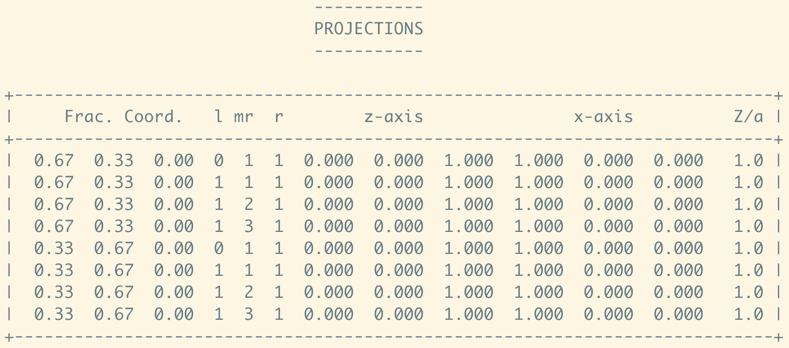

EIGENCAR_DFT = EIGENVAL_read; 
GrapheneWan = HR.from_wannier90()

GrapheneWan =   HR with properties:

    WAN_NUM: 2
      NRPTS: 5
       Type: 'mat'
      HcoeL: [0×0 sym]
      HnumL: [2×2×5 double]
    vectorL: [5×3 double]


%[VarInit,EQL] =GetInit(Graphene,GrapheneWan,[0,0,0])

通过比照


$$E_0^6 =7.41207$$



$$E_1^6 =5.35906$$



$${\textrm{VppP}}_1 =-1.89184$$



$${\textrm{VssS}}_1 =0.346063$$



$${\textrm{VspS}}_1 =4.19456$$



$${\textrm{VppS}}_1 \;\;=\;?$$



$$\delta =?$$


### 构建Bayes 寻参模型

#### 拟合参数设置

设定拟合范围：

options_extra = vasplib.FitOptionHelper(EIGENCAR_DFT,'dirac',...
'Noccu',4,'NBAND_range_DFT',1:4,'highK',[1,20,40,60],'GapThreshold',0.3);    

默认大小和斜率等权

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

-  FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

extra_parm = 0;
Loss_func_TB = @(para,extra_parm) vasplib.loss_func(para,extra_parm, ...
    'FITobj','Graphene',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','dirac' ...
)       

Loss_func_TB = function_handle with value:
    @(para,extra_parm)vasplib.loss_func(para,extra_parm,'FITobj','Graphene','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','dirac')


#### Bayse 模型设置

Varlist = Graphene.symvar_list

$$Varlist = \left(\begin{array}{ccccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} & \delta \end{array}\right)$$

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       E__6_0 |       E__6_1 |       VppP_1 |       VppS_1 |       VspS_1 |       VssS_1 |        delta |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |     0.97463 |     0.51386 |     0.97463 |     0.97463 |       16.438 |       10.513 |      -3.6754 |       5.0659 |       1.1472 |      -6.5352 |      0.80265 |
|    2 | Accept |  4.0584e+05 |     0.40963 |     0.97463 |       23751 |       4.8188 |       1.4721 |  

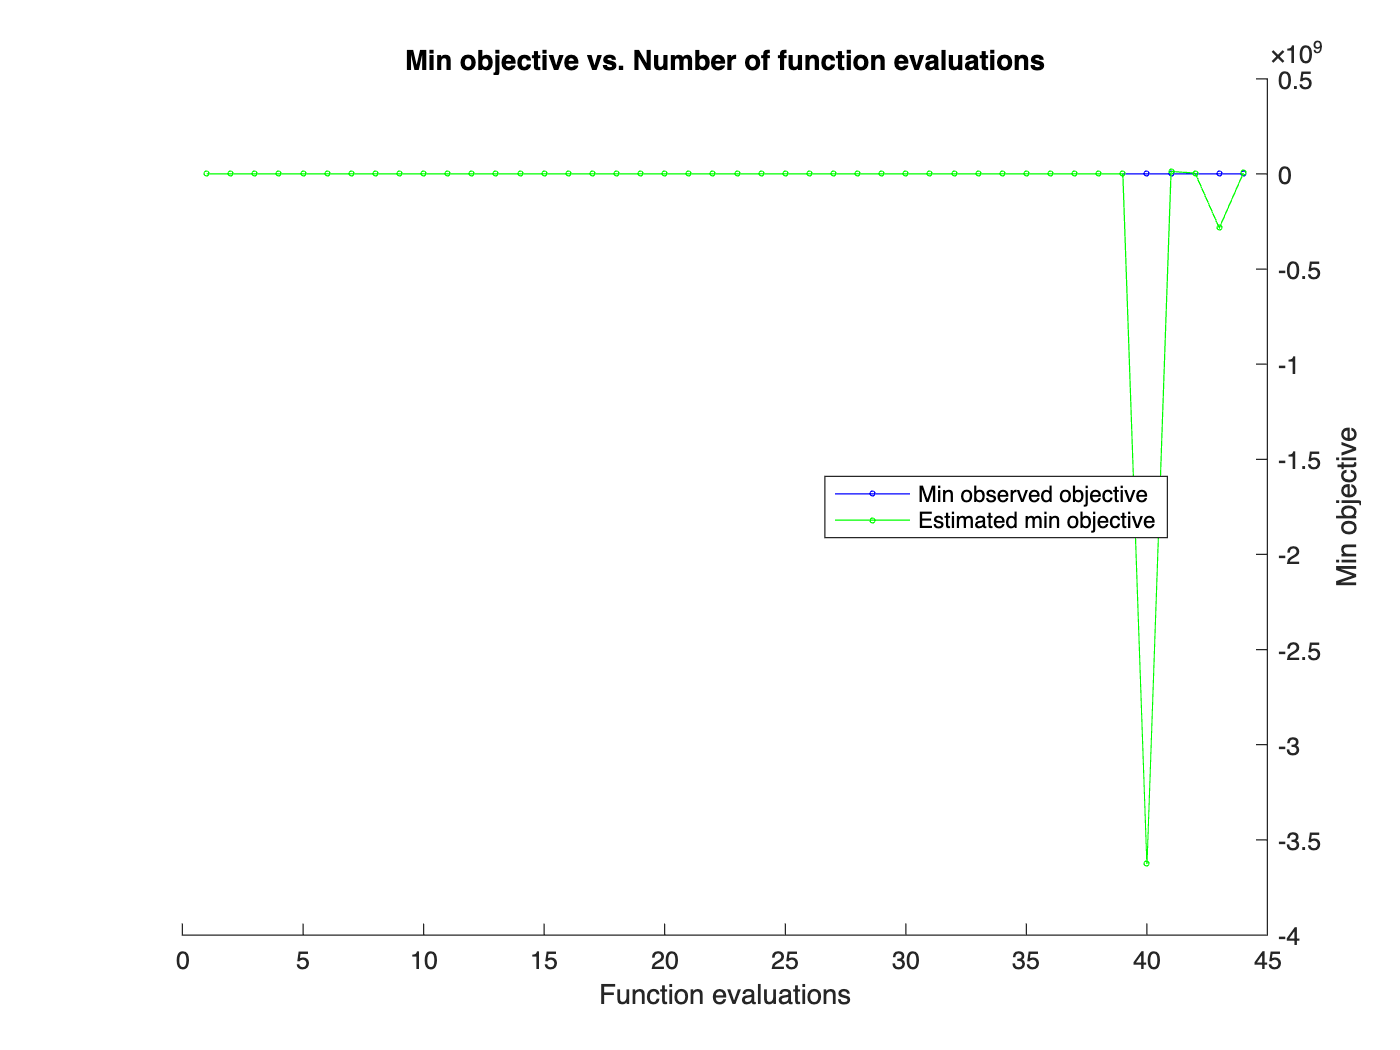

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       E__6_0 |       E__6_1 |       VppP_1 |       VppS_1 |       VspS_1 |       VssS_1 |        delta |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |      4.4342 |     0.37438 |      4.4342 |      4.4342 |      -1.8627 |       2.1488 |      -2.2202 |       8.1276 |      -3.2757 |       4.3691 |      0.79395 |
|    2 | Accept |      16.455 |     0.33879 |      4.4342 |      5.0498 |       7.1284 |      0.13385 |  

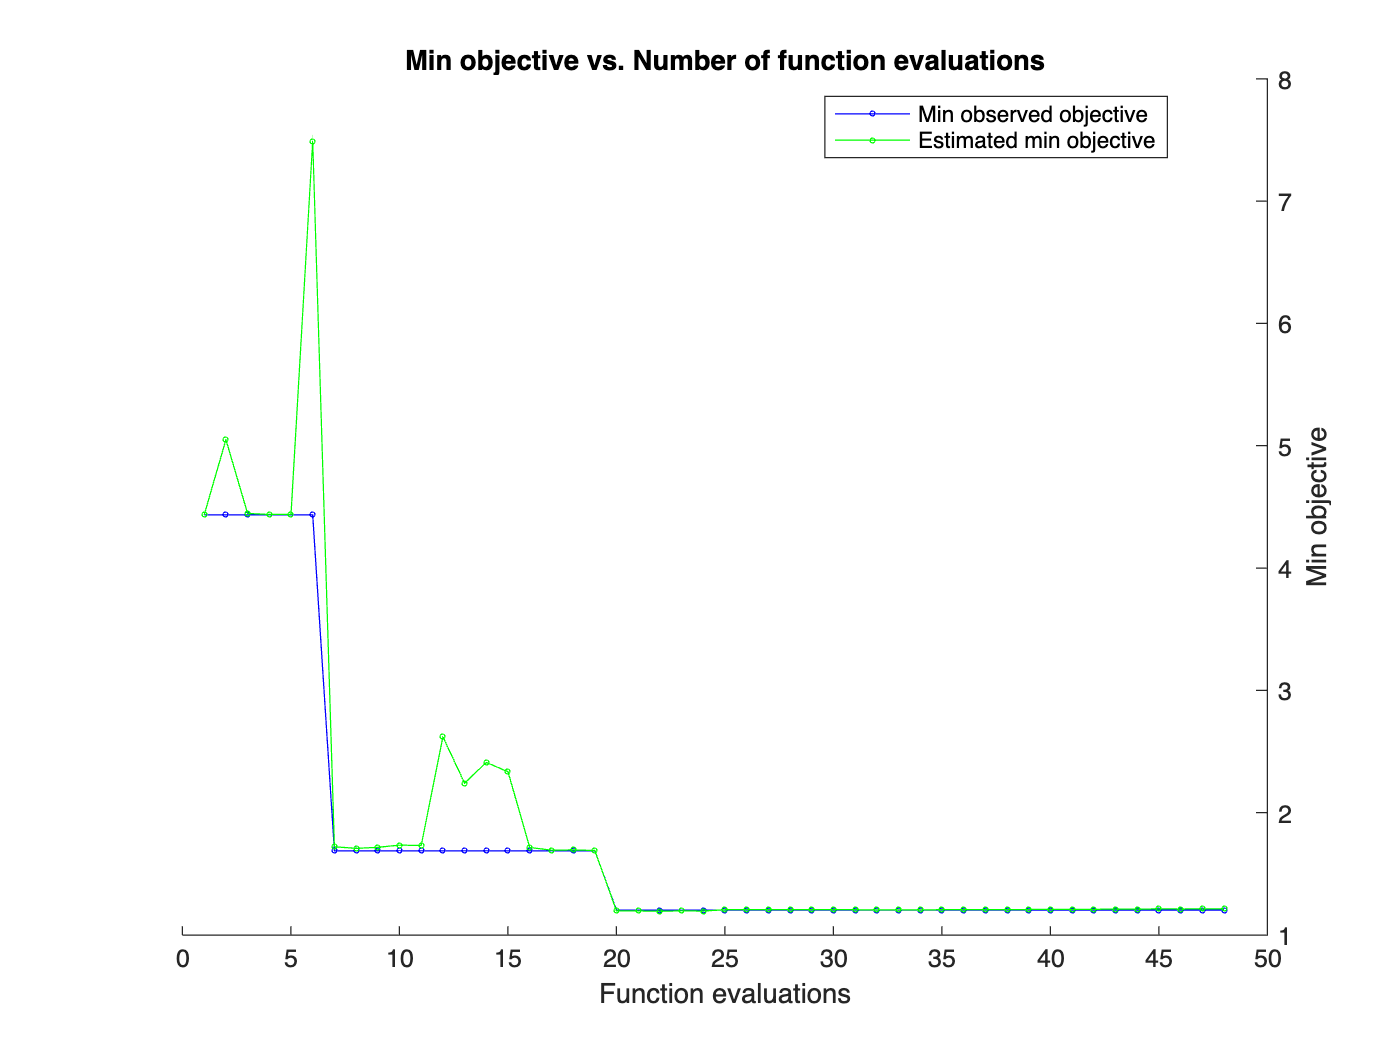

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       E__6_0 |       E__6_1 |       VppP_1 |       VppS_1 |       VspS_1 |       VssS_1 |        delta |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |      3.5955 |     0.37031 |      3.5955 |      3.5955 |      -1.7443 |       1.9655 |      -3.9862 |       9.2621 |      -3.0684 |       3.7193 |        1.301 |
|    2 | Best   |      1.8223 |     0.37044 |      1.8223 |      1.9231 |      0.13069 |       3.4783 |  

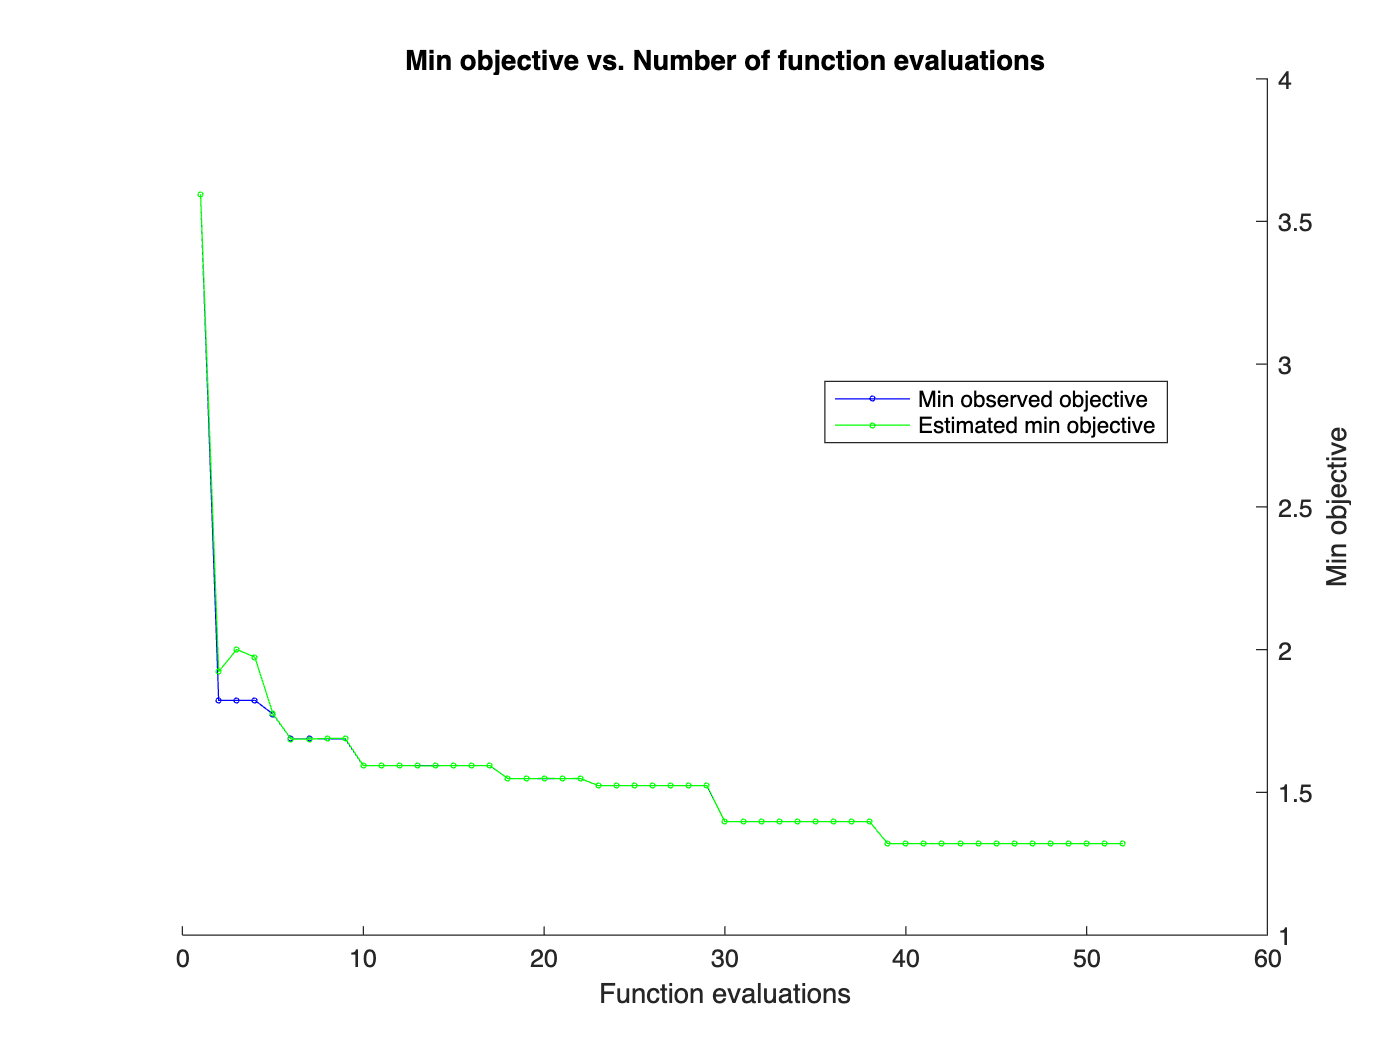

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       E__6_0 |       E__6_1 |       VppP_1 |       VppS_1 |       VspS_1 |       VssS_1 |        delta |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |      1.5139 |     0.38128 |      1.5139 |      1.5139 |     -0.14176 |       3.0495 |      -4.3397 |       8.2334 |      -3.3274 |       5.1411 |       1.1636 |
|    2 | Accept |      1.6613 |     0.37483 |      1.5139 |      1.5233 |      0.02635 |       3.0045 |  

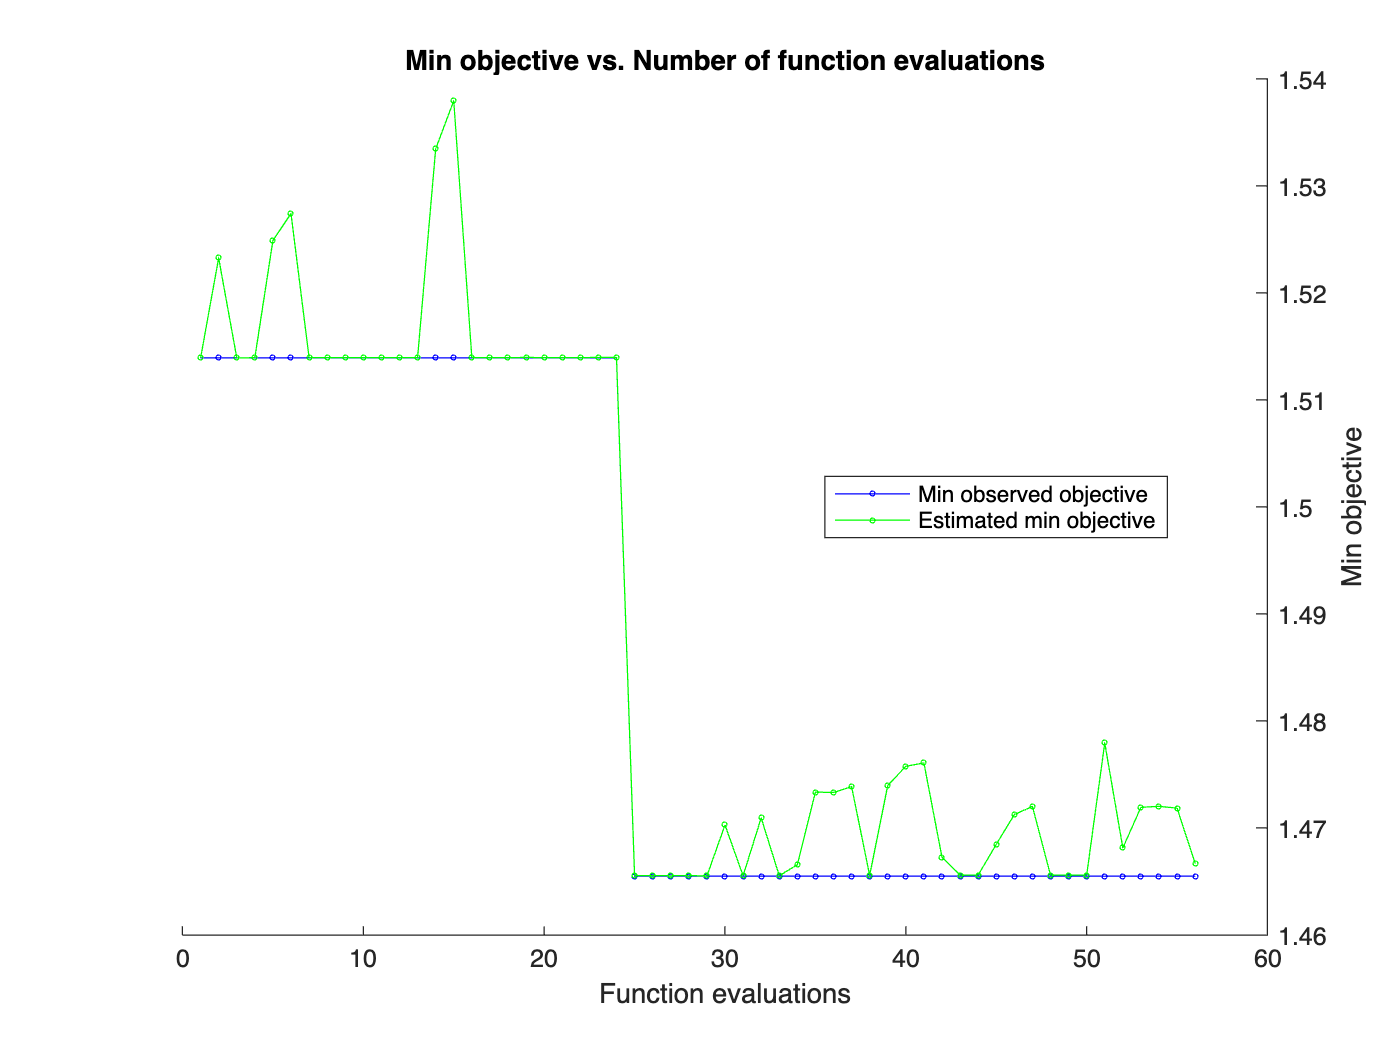

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       E__6_0 |       E__6_1 |       VppP_1 |       VppS_1 |       VspS_1 |       VssS_1 |        delta |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |      1.6653 |     0.39962 |      1.6653 |      1.6653 |     -0.14917 |       3.2741 |      -4.4523 |       8.2029 |      -3.3393 |       5.1227 |       1.1628 |
|    2 | Best   |      1.6454 |     0.36905 |      1.6454 |      1.6464 |      -0.1441 |       3.2816 |  

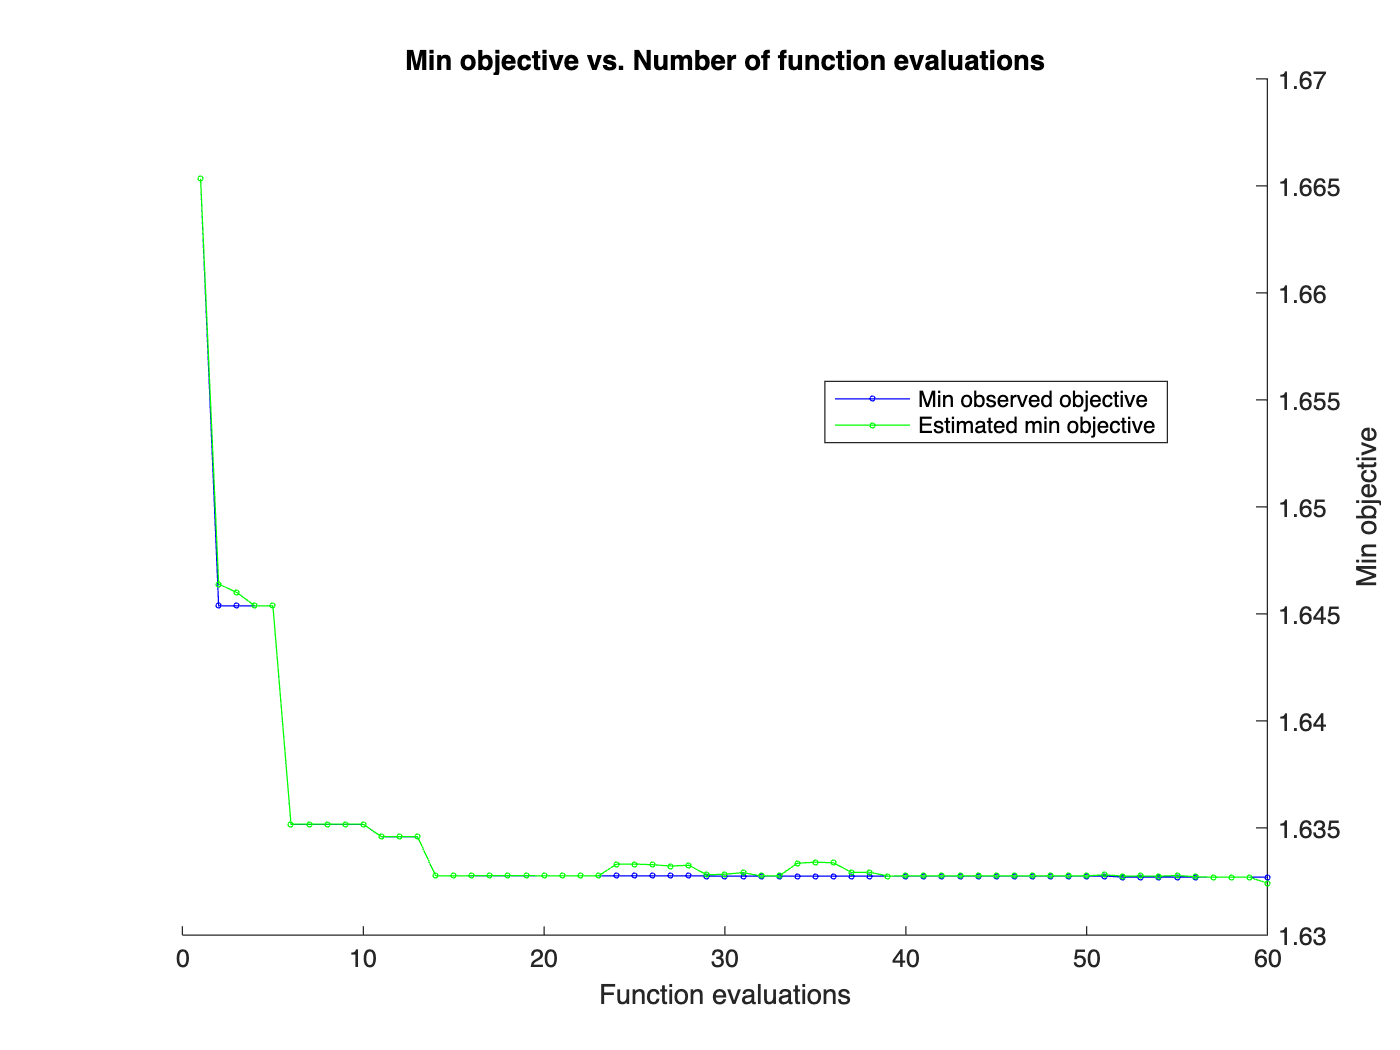

VarGuess = [7.41207,5.353906,-1.8901,0.3456,4.19456,0,0];
Varlock  = VarGuess;
VarFix = sym([]);
VarWidth = [10,10,5,7,7,7,1];
fixCriterion = 1e-2;
BayesCycle = 5;
for i = 1 : BayesCycle
    extra_parm = 1-i/BayesCycle;
    Ratio = 0.7 - 0.4*(i /BayesCycle);
    Max_num = 40 + 20*(i /BayesCycle);
    Loss_func = @(parm) Loss_func_TB(parm,extra_parm);
    %
    VarBayes = vasplib.VarBayes(Varlist,VarGuess,VarWidth,VarFix);
    results = bayesopt(Loss_func,VarBayes,'Verbose',1,...
        'AcquisitionFunctionName','expected-improvement-plus',...
        'ExplorationRatio',Ratio,...
        'MaxObjectiveEvaluations',Max_num ...
        );
    %
    VarGuess_nex_time = table2array(results.XAtMinEstimatedObjective);
    Varlock = VarGuess;
    VarWidth = VarWidth/2^i;
    fixVarible = abs(VarGuess_nex_time - VarGuess) < fixCriterion;
    VarFix = Varlist(fixVarible);
    VarGuess = VarGuess_nex_time;
end

[Graphene_n,EQL] = Graphene.subs(VarGuess);
EQL

$$EQL = \left(\begin{array}{ccccccc} E_{0}^{6}=-0.149784 & E_{1}^{6}=3.28276 & {\mathrm{VppP}}_{1}=-4.451 & {\mathrm{VppS}}_{1}=8.20424 & {\mathrm{VspS}}_{1}=-3.34462 & {\mathrm{VssS}}_{1}=5.13036 & \delta =1.16381 \end{array}\right)$$

EIGENCAR = Graphene_n.EIGENCAR_gen();

BAND calculating 60/60 ...


- 画出能带

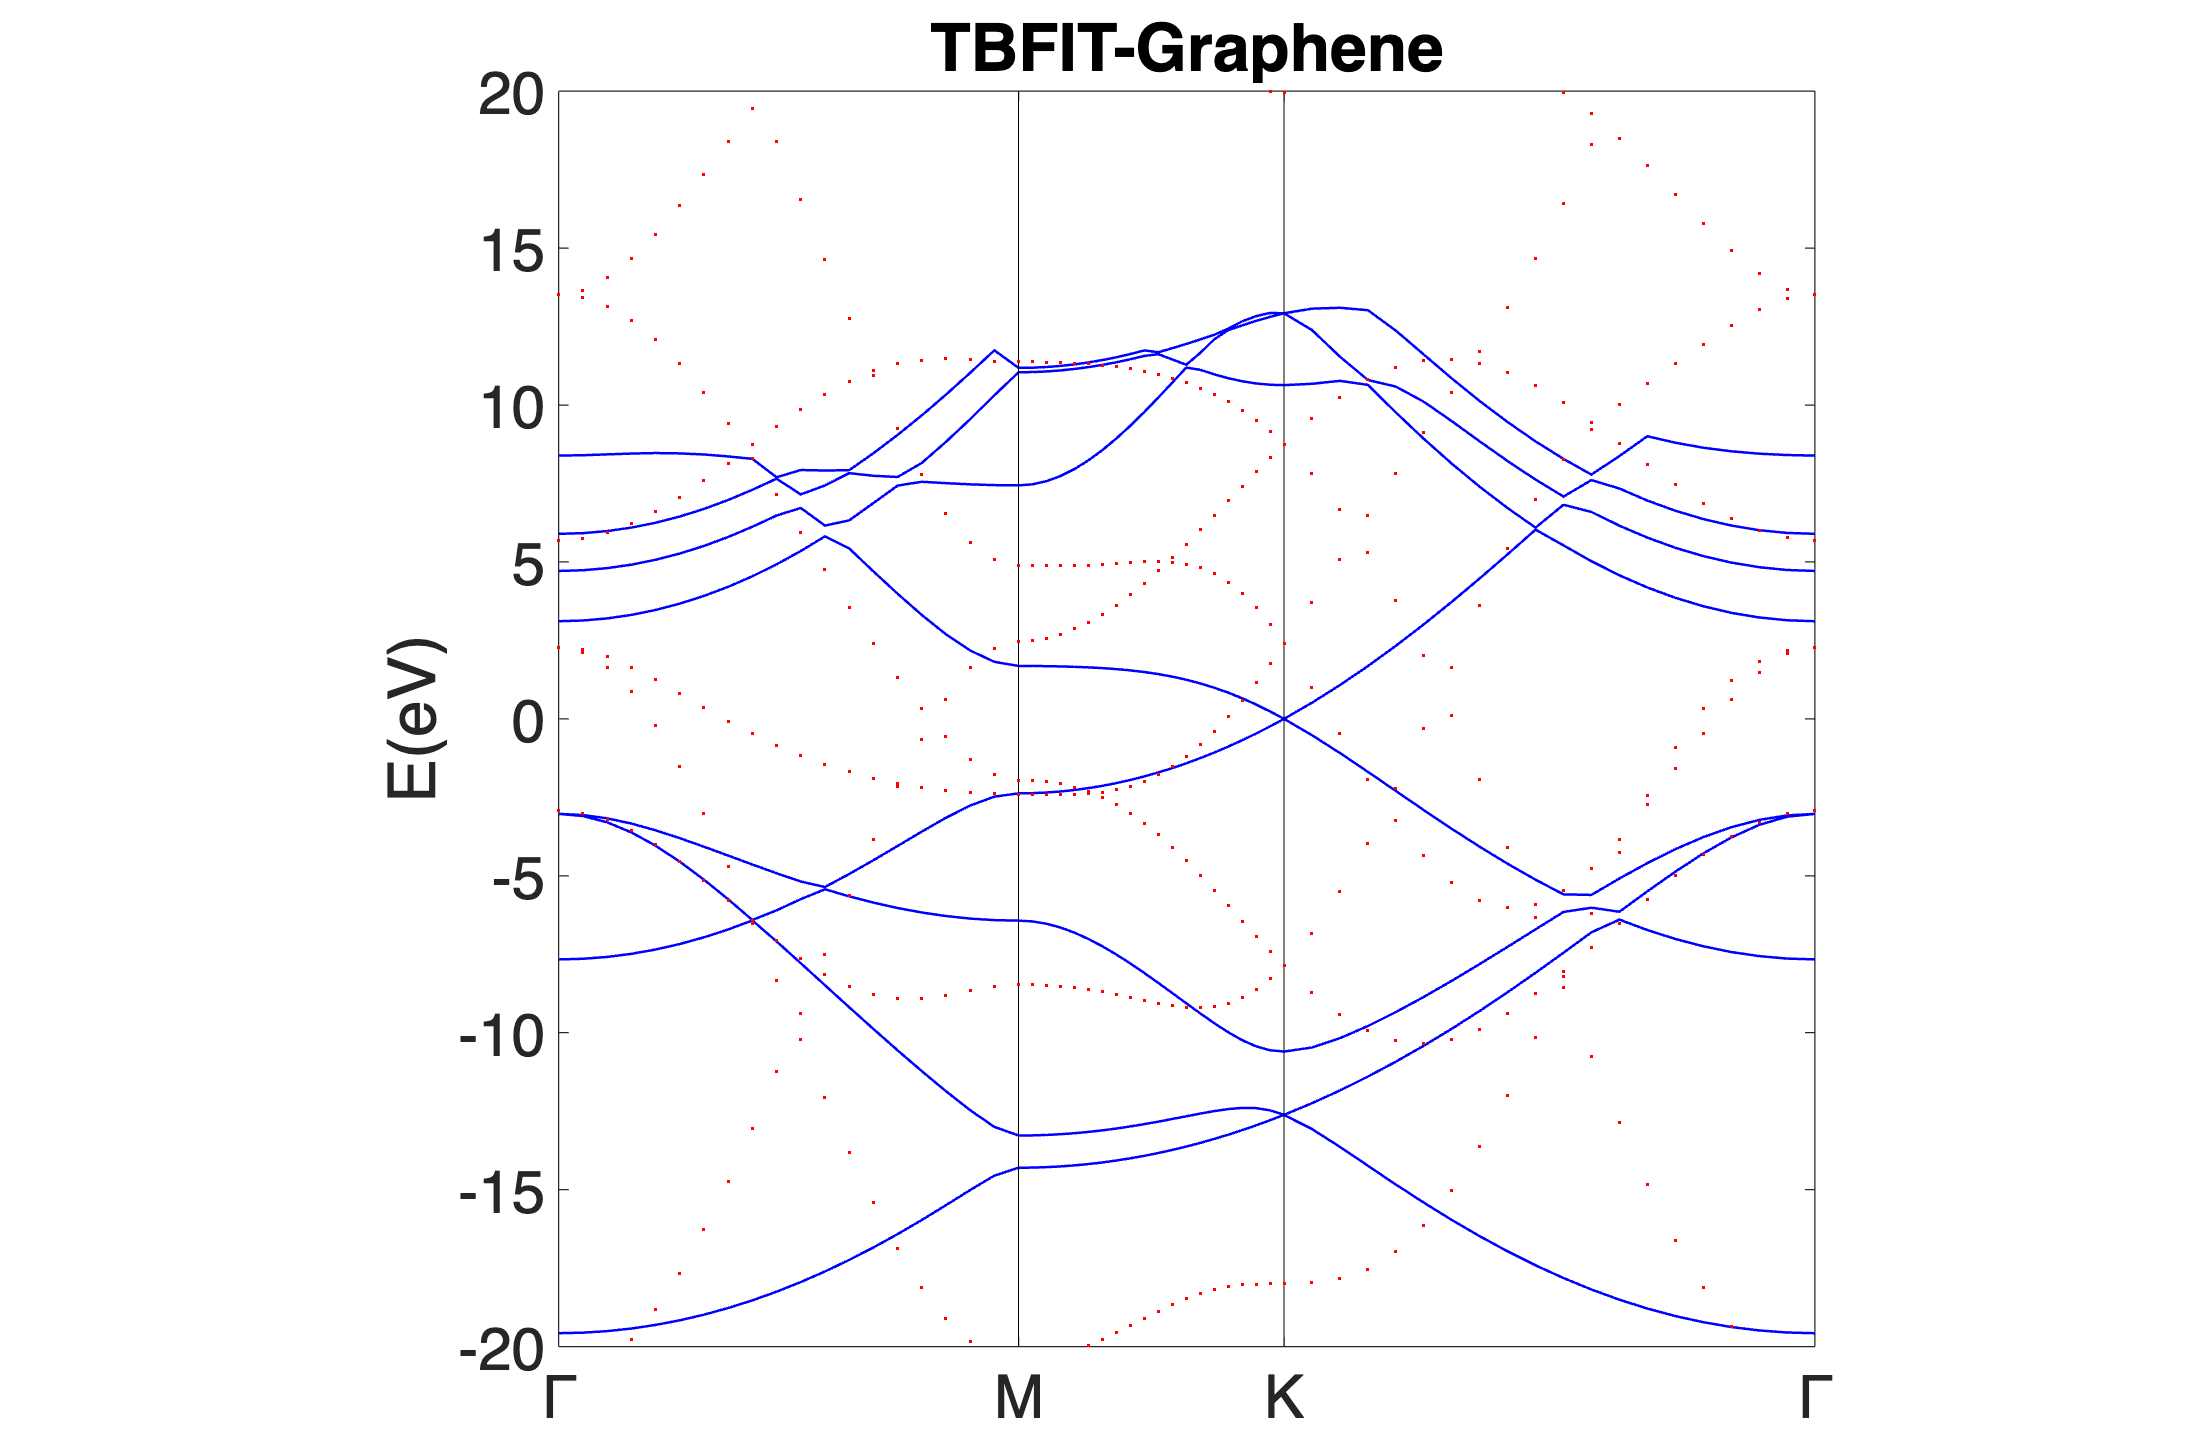

bandcompare(EIGENCAR ,EIGENCAR_DFT,[-20,20]);